a) Clean signal 500Hz with a recording of my "singing"

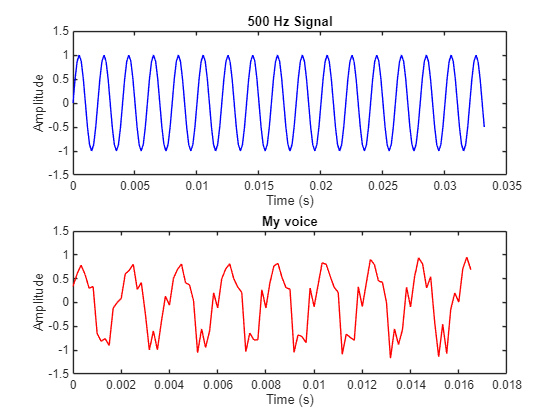

clc;
clear all;
close all;

Fs = 6000;   % Sampling frequency
t = 0:1/Fs:2; % Time vector from 0 to 2 seconds
f = 500;      % Frequency of the sine wave in Hz

clean_signal = sin(2*pi*f*t);
%clean_signal = sampleSin(Fs, 2, 500, 1);


% Plot the clean signal
figure;
subplot(2,1,1);
plot(t(1:200), clean_signal(1:200), 'b');
xlabel('Time (s)');
ylabel('Amplitude');
ylim([-1.5 1.5]);
title('500 Hz Signal');

[My_voice, Fs_recording] = audioread('500_Hz_TEST.wav');



% Ensure the recorded voice and clean signal have the same sampling frequency
if Fs_recording ~= Fs
    error('Sampling frequencies do not match.');
end

% start of the actual signal in the recorded voice
threshold = 0.01; % Define a threshold to detect the start of the signal
start_index = find(abs(My_voice) > threshold, 1);

% Trim initial silence 
My_voice = My_voice(start_index:end);

% Giving same length to the signals:
min_length = min(length(clean_signal), length(My_voice));
clean_signal = clean_signal(1:min_length);
My_voice = My_voice(1:min_length);

% Plot my voice in time domain
subplot(2,1,2)
plot(t(1:100), 21*My_voice(1:100), 'r');
xlabel('Time (s)');
ylabel('Amplitude');
ylim([-1.5 1.5]);
title('My voice');

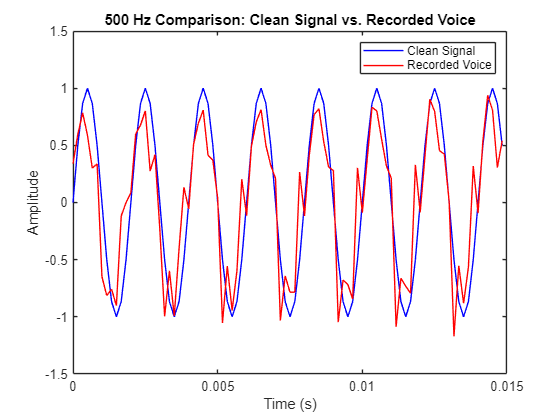


N = 3000;  % To achieve 2 Hz resolution
if length(clean_signal) < N
    clean_signal_padded = [clean_signal, zeros(1, N - length(clean_signal))];
else
    clean_signal_padded = clean_signal(1:N);
end

if length(My_voice) < N
    My_voice_padded = [My_voice', zeros(1, N - length(My_voice))];
else
    My_voice_padded = My_voice(1:N);
end


% Scaling factor
scaling_factor = 21;   %max(abs(clean_signal)) / max(abs(your_voice));
My_voice = My_voice * scaling_factor;

% Time vector for recorded signal
t_voice = (0:length(My_voice)-1)/Fs;

% Plot the first 500 samples of both signals
figure;
plot(t(1:90), clean_signal(1:90), 'b');
hold on;
plot(t_voice(1:90), My_voice(1:90), 'r');

xlabel('Time (s)');
ylabel('Amplitude');
ylim([-1.5 1.5]);
%xlim([0 0.023]);
title('500 Hz Comparison: Clean Signal vs. Recorded Voice');
legend('Clean Signal', 'Recorded Voice');
hold off;

b) A reproduction of the two plotted signals that is in accordance with what I see on the original paper

%Computing the magnitude spectrum for both the clean and recorded signal. 

%Preforming a FFT on both signals to convert them from time domain to the
%freq domain. 

%FFT for both signals 
%N = length(clean_signal);
%clean_signal_fft = fft(clean_signal);
%My_voice_fft = fft(My_voice);
clean_signal_fft = fft(clean_signal_padded) 

clean_signal_fft = 1.0e+03 *

  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i


My_voice_fft = fft(My_voice_padded)

My_voice_fft =    0.1418 + 0.0000i   0.1284 + 0.0071i   0.1325 + 0.0049i   0.1313 - 0.0058i   0.1200 - 0.0014i   0.1238 + 0.0097i   0.1318 + 0.0070i   0.1274 + 0.0065i   0.1323 + 0.0101i   0.1308 + 0.0039i   0.1372 + 0.0152i   0.1264 + 0.0157i   0.1267 + 0.0100i   0.1270 + 0.0177i   0.1261 + 0.0169i   0.1284 + 0.0199i   0.1274 + 0.0208i   0.1273 + 0.0213i   0.1256 + 0.0237i   0.1264 + 0.0242i   0.1277 + 0.0294i   0.1300 + 0.0263i   0.1287 + 0.0311i   0.1286 + 0.0347i   0.1309 + 0.0376i   0.2221 + 0.0859i   0.1350 + 0.0440i   0.1315 + 0.0418i   0.1389 + 0.0499i   0.1408 + 0.0480i   0.1392 + 0.0509i   0.1490 + 0.0564i   0.1504 + 0.0584i   0.1551 + 0.0507i   0.1578 + 0.0485i   0.1558 + 0.0504i   0.1618 + 0.0501i   0.1585 + 0.0542i   0.1633 + 0.0469i   0.1756 + 0.0416i   0.1632 + 0.0416i   0.1658 + 0.0433i   0.1610 + 0.0412i   0.1703 + 0.0476i   0.1654 + 0.0432i   0.1671 + 0.0444i   0.1718 + 0.0360i   0.1698 + 0.0296i   0.1679 + 0.0389i   0.1703 + 0.0415i



frequency_resolution = Fs / N;
fprintf('The frequency resolution is %.2f Hz.\n', frequency_resolution);

The frequency resolution is 2.00 Hz.


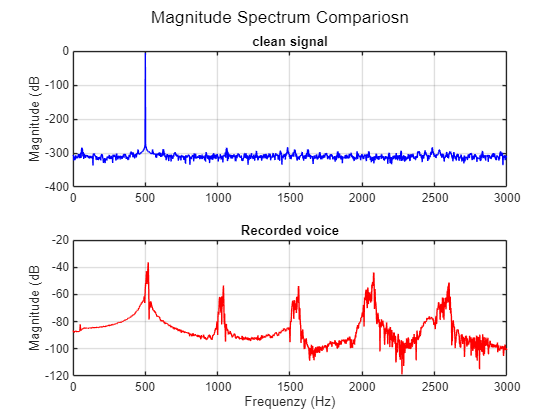


%freq axis
freq_axis = (0:N-1)*(Fs/N);

%Magnitude in dB
clean_signal_magnitude = 20*log10(abs(clean_signal_fft)/N);
My_voice_magnitude = 20*log10(abs(My_voice_fft)/N);

% Apply threshold to magnitude spectrum
%clean_signal_magnitude(clean_signal_magnitude < -100) = -100;
%My_voice_magnitude(My_voice_magnitude < -100) = -100;

%Plotting 
figure;
sgtitle('Magnitude Spectrum Compariosn')

subplot(2,1,1);
plot(freq_axis(1:N/2), clean_signal_magnitude(1:N/2), 'b'); %(1:N/2)
ylabel('Magnitude (dB');
xlim([0 3000]);
title('clean signal');
grid on;

subplot(2,1,2);
plot(freq_axis(1:N/2), My_voice_magnitude(1:N/2), 'r');    %(1:N/2)
xlabel('Frequenzy (Hz)');
ylabel('Magnitude (dB');
xlim([0 3000]);
title('Recorded voice');
grid on;


% Debugging: Check the peak frequency
[~, peak_index_clean] = max(clean_signal_magnitude);
[~, peak_index_voice] = max(My_voice_magnitude);

peak_frequency_clean = freq_axis(peak_index_clean);
peak_frequency_voice = freq_axis(peak_index_voice);

disp(['Peak frequency of clean signal: ', num2str(peak_frequency_clean), ' Hz']);

Peak frequency of clean signal: 500 Hz


disp(['Peak frequency of recorded voice: ', num2str(peak_frequency_voice), ' Hz']);

Peak frequency of recorded voice: 520 Hz
